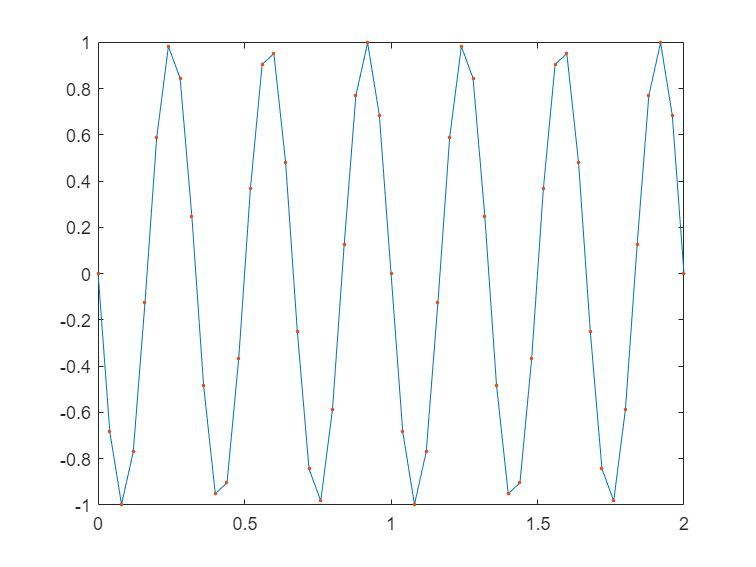

% Signal
k = 2;
N = 51;
freq = 47;
t = linspace(0,1*k,N);
y = sin(2*pi*freq*t);

% FFT
T = (t(end)-t(1))/length(t);
Fs = 1/T;
F = fft(y);
P2 = (abs(F/N));
Nhalf = round(N/2);
P1 = P2(1:Nhalf+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(Nhalf))/N;


plot(t,y,'-',t,y,'.')

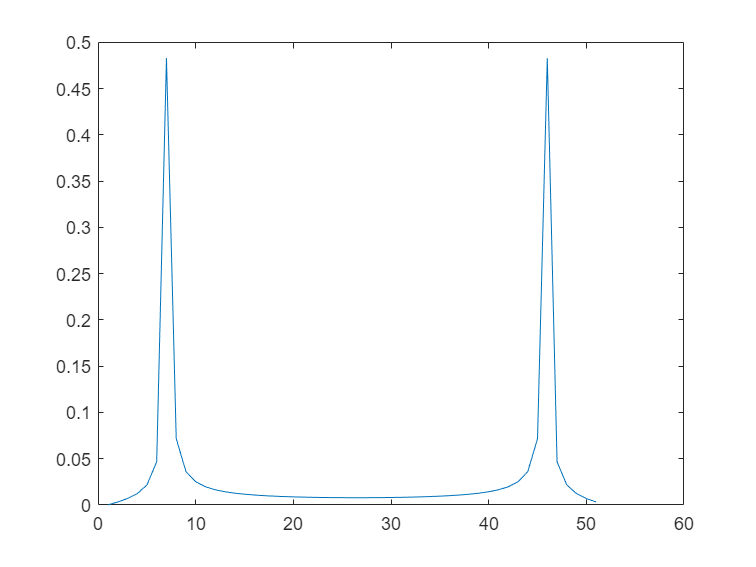

plot(P2)